global L alpha
n = 9;
m = 14;
d = 3;
size = 1;
alpha = 0.75;
rng(3);

s = [1 1 2 2 3 3 4 4 5 5 6 7 7 8];
t1 = [2 3 3 4 4 5 5 6 7 9 7 8 9 9];
G = graph(s,t1);
H = incidence(G)'*eye(9);
A12 = [1, sqrt(3)/2, 0; sqrt(3)/2, 1, 0; 0, 0, 0];
A13 = [0 0 0; 0 1 0; 0 0 1];
A23 = [2 1 0; 1 1 0; 0 0 1];
A24 = A13; A34 = A13;
A35 = [1 0 0; 0 0 0; 0 0 0];
A45 = diag([1, 2, 3]);
A78 = eye(3);
A79 = eye(3);
A89 = ones(3,3);
A46 = A89;
A67 = A12;
A57 = A35;
A59 = A13;
W = blkdiag(A12,A13,A23,A24,A34,A35,A45,A46,A57,A59,A67,A78,A79,A89);

Hbar = kron(H,eye(d));
L = Hbar'*W*Hbar;
lambda_max = max(v(v>0.0001))

lambda_max = 9.9488

delay_max = 2*pi/lambda_max

delay_max = 0.6316

tau = 0.30;

t_end = 30;
x0 = 10*(rand(d*n,1)-0.5);
%tau = 0.1;
% Simulink simulation
err1percent = 0.0005*norm(L*x0)

err1percent = 0.0260

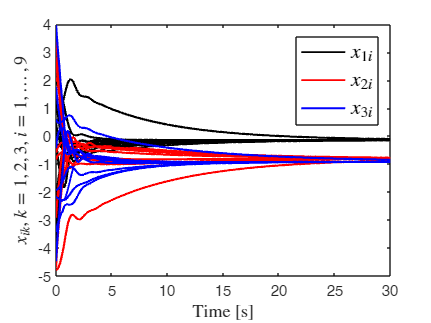


modelName = 'c9_acc_via_delays';
set_param(modelName,"StartTime","0","StopTime","30")
sim(modelName);

t1 = ans.ScopeData{1}.Values.Time;
r1 = ans.ScopeData{1}.Values.Data(:,1:d*n);

figure
hold on
plot(t1,r1(:,1),"LineWidth",1.25,"Color",'k');
plot(t1,r1(:,2),"LineWidth",1.25,"Color",'r');
plot(t1,r1(:,3),"LineWidth",1.25,"Color",'b');
plot(t1,r1(:,d+1:d:d*n),"LineWidth",1.5,"Color",'k');
plot(t1,r1(:,d+2:d:d*n),"LineWidth",1.5,"Color",'r');
plot(t1,r1(:,d+3:d:d*n),"LineWidth",1.5,"Color",'b');
legend({'$x_{1i}$','$x_{2i}$','$x_{3i}$'},"Interpreter","latex","FontSize",14,"NumColumns",1)
xlabel('Time [s]',"FontSize",12)
ylabel('$x_{ik},~k=1,2,3,~i=1,\ldots,9$',"Interpreter","latex","FontSize",12)
box on

%grid on

e1 = zeros(length(t1),1); r1 = r1';
for i=1:length(t1)
    e1(i,1) = norm(L*r1(:,i));
end
r1 = find(e1<err1percent,1,'first')

r1 = 24793

t1(r1)

ans = 24.7919

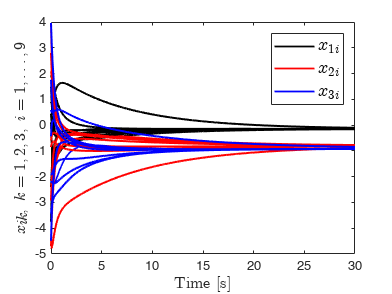

modelName1 = 'c9_acc_without_delays';
set_param(modelName1,"StartTime","0","StopTime","30")
sim(modelName1);

t2 = ans.ScopeData{1}.Values.Time;
r2 = ans.ScopeData{1}.Values.Data(:,1:d*n);

figure
hold on
plot(t2,r2(:,1),"LineWidth",1.25,"Color",'k');
plot(t2,r2(:,2),"LineWidth",1.25,"Color",'r');
plot(t2,r2(:,3),"LineWidth",1.25,"Color",'b');
plot(t2,r2(:,d+1:d:d*n),"LineWidth",1.5,"Color",'k');
plot(t2,r2(:,d+2:d:d*n),"LineWidth",1.5,"Color",'r');
plot(t2,r2(:,d+3:d:d*n),"LineWidth",1.5,"Color",'b');
legend({'$x_{1i}$','$x_{2i}$','$x_{3i}$'},"Interpreter","latex","FontSize",14,"NumColumns",1)
xlabel('Time [s]',"FontSize",12)
ylabel('$x_{ik},~k=1,2,3,~i=1,\ldots,9$',"Interpreter","latex","FontSize",12)
box on

%grid on

e2 = zeros(length(t2),1); r2 = r2';
for i=1:length(t2)
    e2(i,1) = norm(L*r2(:,i));
end
r2 = find(e2<err1percent,1,'first')

r2 = 25244

t2(r2)

ans = 25.2410

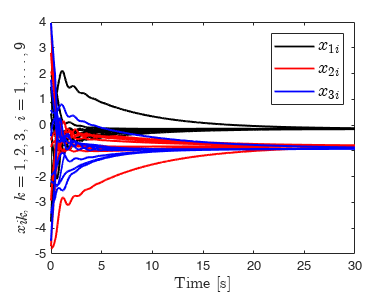


modelName = 'c9_acc_via_delays1';
set_param(modelName,"StartTime","0","StopTime","30")
tau = 0.2;
sim(modelName);

t3 = ans.ScopeData{1}.Values.Time;
r3 = ans.ScopeData{1}.Values.Data(:,1:d*n);

figure
hold on
plot(t3,r3(:,1),"LineWidth",1.25,"Color",'k');
plot(t3,r3(:,2),"LineWidth",1.25,"Color",'r');
plot(t3,r3(:,3),"LineWidth",1.25,"Color",'b');
plot(t3,r3(:,d+1:d:d*n),"LineWidth",1.5,"Color",'k');
plot(t3,r3(:,d+2:d:d*n),"LineWidth",1.5,"Color",'r');
plot(t3,r3(:,d+3:d:d*n),"LineWidth",1.5,"Color",'b');
legend({'$x_{1i}$','$x_{2i}$','$x_{3i}$'},"Interpreter","latex","FontSize",14,"NumColumns",1)
xlabel('Time [s]',"FontSize",12)
ylabel('$x_{ik},~k=1,2,3,~i=1,\ldots,9$',"Interpreter","latex","FontSize",12)
box on

%grid on

e3 = zeros(length(t3),1); r3 = r3';
for i=1:length(t3)
    e3(i,1) = norm(L*r3(:,i));
end
r3 = find(e3<err1percent,1,'first')

r3 = 22575

t3(r3)

ans = 22.5740

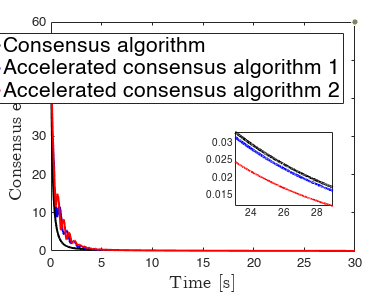



figure
hold on
plot(t2,e2,"-k","LineWidth",1.5);
plot(t1,e1,"-b","LineWidth",1.5);
plot(t3,e3,"-r","LineWidth",1.5);
box on
xlabel('Time [s]',"FontSize",14);
ylabel('Consensus error',"FontSize",14);
legend({'Consensus algorithm','Accelerated consensus algorithm 1','Accelerated consensus algorithm 2'},"FontSize",16,"NumColumns",1)
% 
% ax = axes('position',[0.5 .2 .3 .3]);
% box on % put box around new pair of axes
% hold on
% indexOfInterest = (t1 <= 15) & (t1 >= 12); % range of t near perturbation
% plot(t1(indexOfInterest),e1(indexOfInterest),"-k","LineWidth",2); % plot on new axes
% plot(t2(indexOfInterest),e2(indexOfInterest),"-b","LineWidth",2); % plot on new axes
% plot(t3(indexOfInterest),e3(indexOfInterest),"-r","LineWidth",2); % plot on new axes
% axis tight
% box on;

ax = axes('position',[0.6 .3 .25 .25]);
box on % put box around new pair of axes
hold on
indexOfInterest = (t1 <= 29) & (t1 >= 23); % range of t near perturbation
plot(t3(indexOfInterest),e3(indexOfInterest),"-r","LineWidth",1.5); % hold on % plot on new axes
plot(t2(indexOfInterest),e2(indexOfInterest),"-k","LineWidth",2); % plot on new axes
plot(t1(indexOfInterest),e1(indexOfInterest),"-b","LineWidth",2); % plot on new axes
axis tight
box on;